# Component contribution: analysis of updated method applied to Recon3D

## **Author: Ronan Fleming, **School of Medicine, University of Galway

## **Reviewers: **

## INTRODUCTION

## PROCEDURE

## Configure the environment

All the installation instructions are in a separate .md file named vonBertalanffy.md in docs/source/installation

With all dependencies installed correctly, we configure our environment, verfy all dependencies, and add required fields and directories to the matlab path.

aPath = which('initVonBertalanffy');
basePath = strrep(aPath,'vonBertalanffy/initVonBertalanffy.m','');
addpath(genpath(basePath))
folderPattern=[filesep 'old'];
method = 'remove';
editCobraToolboxPath(basePath,folderPattern,method)

removing: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/componentContribution/old
removing: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/directionalityReport/old
removing: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/groupContribution/old
removing: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/inchi/old
removing: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/molFiles/old
removing: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/protons/old
removing: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/trainingModel/old


aPath = which('initVonBertalanffy');
basePath = strrep(aPath,'vonBertalanffy/initVonBertalanffy.m','');
addpath(genpath(basePath))
folderPattern=[filesep 'new'];
method = 'add';
editCobraToolboxPath(basePath,folderPattern,method)

adding: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/componentContribution/new
adding: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/groupContribution/new
adding: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/inchi/new
adding: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/molFiles/new
adding: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/protons/new
adding: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/trainingModel/new


initVonBertalanffy

ChemAxon Marvin Beans is installed and working.
	linux-vdso.so.1 (0x00007ffc78f8b000)
	libc.so.6 => /lib/x86_64-linux-gnu/libc.so.6 (0x00007fd52933b000)
	libopenbabel.so.5 => /usr/lib/libopenbabel.so.5 (0x00007fd5290eb000)
	libstdc++.so.6 => /usr/lib/x86_64-linux-gnu/libstdc++.so.6 (0x00007fd528ed1000)
	libgcc_s.so.1 => /usr/local/bin/MATLAB/R2021a/sys/os/glnxa64/libgcc_s.so.1 (0x00007fd528cb9000)
	/lib64/ld-linux-x86-64.so.2 (0x00007fd52955b000)
	libdl.so.2 => /lib/x86_64-linux-gnu/libdl.so.2 (0x00007fd528cb1000)
	libz.so.1 => /lib/x86_64-linux-gnu/libz.so.1 (0x00007fd528c95000)
	libm.so.6 => /lib/x86_64-linux-gnu/libm.so.6 (0x00007fd528b46000)
	libgomp.so.1 => /usr/lib/x86_64-linux-gnu/libgomp.so.1 (0x00007fd528b01000)
	libpthread.so.0 => /lib/x86_64-linux-gnu/libpthread.so.0 (0x00007fd528ade000)

babel must depend on the system libstdc++.so.6 not the one from MATLAB
Trying to edit the 'LD_LIBRARY_PATH' to make sure that it has the correct system path before the Matlab path!
The solu

Load data input for component contribution method

load('data_prior_to_componentContribution')

## Component Contribution

Run component contribution method

param.debug = 1;
[model,solution] = componentContribution(model,combinedModel,param);

Running Component Contribution method


## Comparison of weighting of reactant and group contribution for training metabolites

X = combinedModel.S;
XR = solution.PR_St*X;
XN = solution.PN_St*X;
XNR = (solution.PN_St - solution.PN_StGGt)*X;
XNN = solution.PN_StGGt*X;

Check that the decomposition into different components is complete

norm(X - (XR + XN),'inf')

ans = 4.7851e-14

norm(XN - (XNR + XNN),'inf')

ans = 9.2198e-14

norm(X - (XR + XNR + XNN),'inf')

ans = 8.1953e-14

Stoichiometric degree

dX = diag(X*X');
fprintf('%u%s\n',nnz(dX),' metabolites with non-zero training stoichiometric degree')

668 metabolites with non-zero training stoichiometric degree


fprintf('%u%s\n',nnz(dX==0),' metabolites with zero training stoichiometric degree')

2998 metabolites with zero training stoichiometric degree


dXR = diag(XR*XR');
fprintf('%u%s\n',nnz(dXR),' metabolites with non-zero training stoichiometric degree, in the range of S''')

671 metabolites with non-zero training stoichiometric degree, in the range of S'


fprintf('%u%s\n',nnz(dXR==0),' metabolites with zero training stoichiometric degree, in the range of S''')

2995 metabolites with zero training stoichiometric degree, in the range of S'


dXN = diag(XN*XN');
fprintf('%u%s\n',nnz(dXN),' metabolites with non-zero training stoichiometric degree, in the nullspace of S''')

654 metabolites with non-zero training stoichiometric degree, in the nullspace of S'


fprintf('%u%s\n',nnz(dXN==0),' metabolites with zero training stoichiometric degree, in the nullspace of S''')

3012 metabolites with zero training stoichiometric degree, in the nullspace of S'


dXNR = diag(XNR*XNR');
fprintf('%u%s\n',nnz(dXNR),' metabolites with non-zero training stoichiometric degree, in the nullspace of S'' and G''x in the range of G''S')

2656 metabolites with non-zero training stoichiometric degree, in the nullspace of S' and G'x in the range of G'S


fprintf('%u%s\n',nnz(dXNR==0),' metabolites with zero training stoichiometric degree, in the nullspace of S'' and G''x in the range of G''S')

1010 metabolites with zero training stoichiometric degree, in the nullspace of S' and G'x in the range of G'S


dXNN = diag(XNN*XNN');
fprintf('%u%s\n',nnz(dXNN),' metabolites with non-zero training stoichiometric degree, in the nullspace of S'' and in the nullspace of S''GG'' ')

2648 metabolites with non-zero training stoichiometric degree, in the nullspace of S' and in the nullspace of S'GG' 


fprintf('%u%s\n',nnz(dXNN==0),' metabolites with zero training stoichiometric degree, in the nullspace of S'' and in the nullspace of S''GG'' ')

1018 metabolites with zero training stoichiometric degree, in the nullspace of S' and in the nullspace of S'GG' 


norm(dX - (dXR + dXN),'inf')

ans = 6.5938e-12

norm(dXN - (dXNR + dXNN),'inf')

ans = 3.2797e+03


norm(dX - (dXR + dXNR + dXNN),'inf')

ans = 3.2797e+03

norm(dX.^2 - (dXR.^2 + dXNR.^2 + dXNN.^2),'inf')

ans = 5.3781e+06

Sort by stoichiometric degree of reactant contribution (for each metabolite)

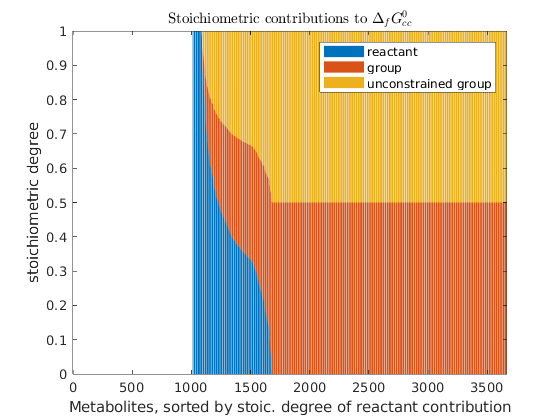

dXtotal = dXR + dXNR + dXNN;
Y = [dXR./dXtotal,dXNR./dXtotal,dXNN./dXtotal];
[dXRsorted,xi]=sort(dXR./dXtotal,'descend');
figure
bar(Y(xi,:),'stacked')
ylim([0 1])
title('Stoichiometric contributions to $\Delta_{f} G^{0}_{cc}$','Interpreter','latex')
xlabel('Metabolites, sorted by stoic. degree of reactant contribution')
ylabel('stoichiometric degree')
legend({'reactant','group','unconstrained group'})

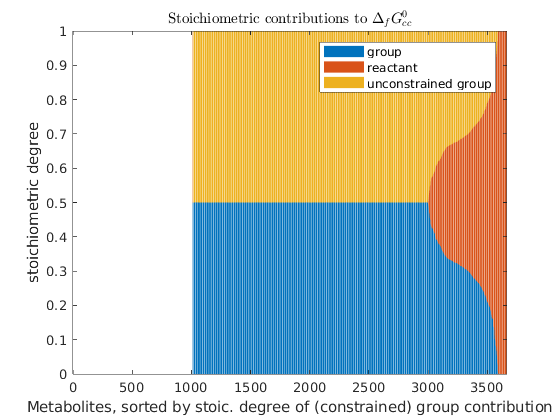

Y = [dXNR./dXtotal,dXR./dXtotal,dXNN./dXtotal];
[~,xi]=sort(dXNR./dXtotal,'descend');
figure
bar(Y(xi,:),'stacked')
ylim([0 1])
title('Stoichiometric contributions to $\Delta_{f} G^{0}_{cc}$','Interpreter','latex')
xlabel('Metabolites, sorted by stoic. degree of (constrained) group contribution')
ylabel('stoichiometric degree')
legend({'group','reactant','unconstrained group'})

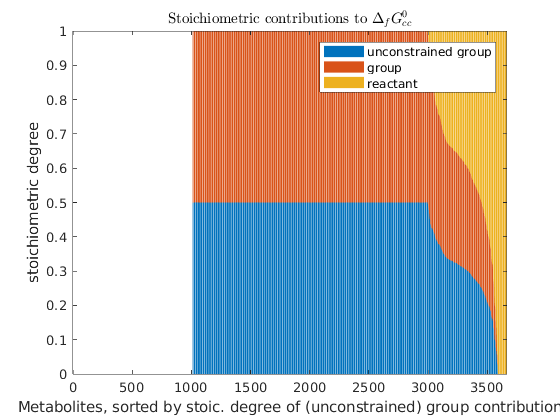

Y = [dXNN./dXtotal,dXNR./dXtotal,dXR./dXtotal];
[~,xi]=sort(dXNN./dXtotal,'descend');
figure
bar(Y(xi,:),'stacked')
ylim([0 1])
title('Stoichiometric contributions to $\Delta_{f} G^{0}_{cc}$','Interpreter','latex')
xlabel('Metabolites, sorted by stoic. degree of (unconstrained) group contribution')
ylabel('stoichiometric degree')
legend({'unconstrained group','group','reactant'})

## Analyse reactant contribution

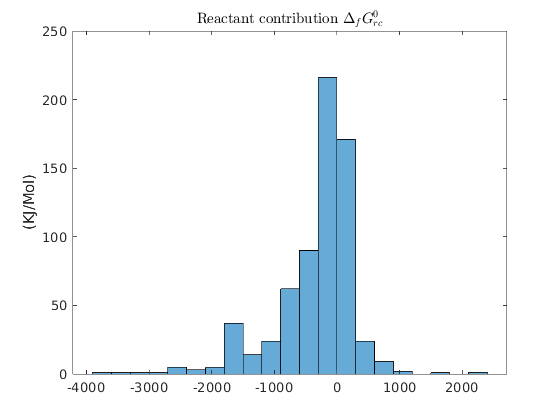

figure
histogram(solution.DfG0_rc(~solution.unconstrainedDfG0_rc))
title('$\textrm{Reactant contribution } \Delta_{f} G^{0}_{rc}$','Interpreter','latex')
ylabel('(KJ/Mol)')

nCombinedMet=size(combinedModel.S,1);
fprintf('%u%s\n',nCombinedMet,' formation energies')

3666 formation energies


fprintf('%u%s\n',nnz(solution.unconstrainedDfG0_rc),' of which DfG0_rc are unconstrained. i.e., number of formation energies that cannot be determined by reactant contribution')

2998 of which DfG0_rc are unconstrained. i.e., number of formation energies that cannot be determined by reactant contribution


fprintf('%g%s\n',nnz(solution.unconstrainedDfG0_rc)/nCombinedMet,' = fraction of DfG0 unconstrained by reactant contribution.')

0.817785 = fraction of DfG0 unconstrained by reaction contribution.


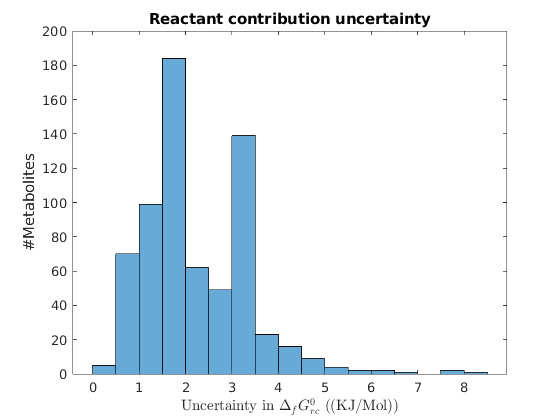

figure
histogram(solution.DfG0_rc_Uncertainty(~solution.unconstrainedDfG0_rc))
title('Reactant contribution uncertainty')
ylabel('#Metabolites')
xlabel('Uncertainty in $\Delta_{f} G^{0}_{rc}$  ((KJ/Mol))','Interpreter','latex')

fprintf('%g%s\n',nnz(solution.DfG0_rc_Uncertainty==0 & ~solution.unconstrainedDfG0_rc),' number of zero uncertainty in constrained DfG0_rc')

0 number of zero uncertainty in constrained DfG0_rc


fprintf('%g%s\n',nnz(solution.DfG0_rc_Uncertainty==0 & solution.unconstrainedDfG0_rc),' number of zero uncertainty in unconstrained DfG0_rc')

2998 number of zero uncertainty in unconstrained DfG0_rc


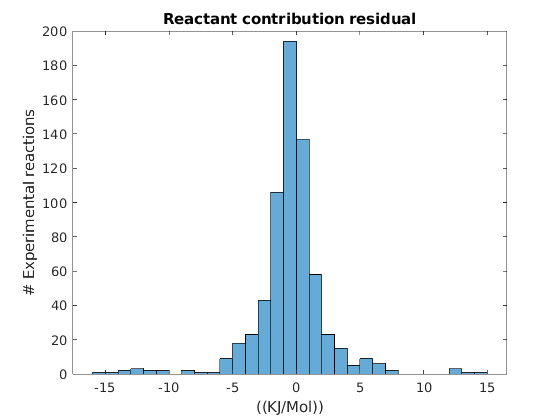

figure;
histogram(solution.e_rc(~solution.unconstrainedDfG0_rc))
text(-30,700,{['MSE = ' num2str(solution.MSE_rc)],['MAE = ' num2str(solution.MAE_rc)]});
title('Reactant contribution residual')
xlabel('((KJ/Mol))');
ylabel('# Experimental reactions')

Experiments contributing the largest to residuals in the reactant contribution method

 [rcErrorSorted,rcSI]=sort(solution.e_rc);
 N=10;
 for i=1:N
     rxnFormula = printRxnFormula(combinedModel,'rxnAbbrList',combinedModel.rxns(rcSI(i)),'printFlag',0);
     fprintf('%g\t%s\t%s\n',solution.e_rc(rcSI(i)),combinedModel.rxns{rcSI(i)},rxnFormula{1});
 end

-31.6414	TECRDB_1919	C00002 + C01281  -> C00013 + C01299 
-26.9545	TECRDB_1929	C00002 + C01281  -> C00013 + C01299 
-21.9955	TECRDB_1920	C00002 + C01281  -> C00013 + C01299 
-20.5893	FORM_C00093	 -> C00093 
-17.7694	FORM_C01127	 -> C01127 
-15.2367	TECRDB_539	C00002 + C00300  -> C00008 + C02305 
-15.1381	TECRDB_2655	C00003 + C00197  -> C00004 + C03232 
-14.375	TECRDB_3728	C00003 + C00469  -> C00004 + C00084 
-14.2817	TECRDB_374	C00006 + C00342  -> C00005 + C00343 
-13.4218	TECRDB_237	C00002 + C00062  -> C00008 + C05945 


## Analyse group contribution

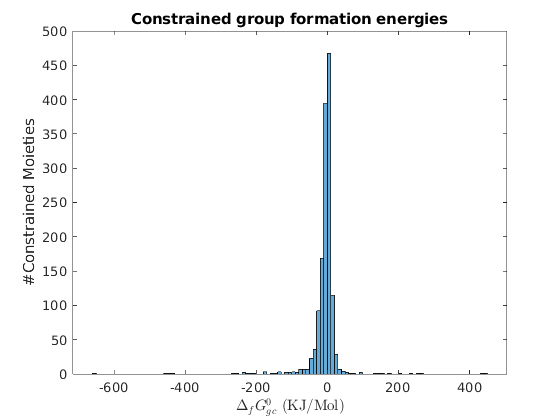

 figure
 histogram(solution.DfG0_gc(~solution.unconstrainedDfG0_gc))
 title('Constrained group formation energies')
xlabel('$\Delta_{f} G^{0}_{gc}$ (KJ/Mol)','Interpreter','latex')
ylabel('#Constrained Moieties')

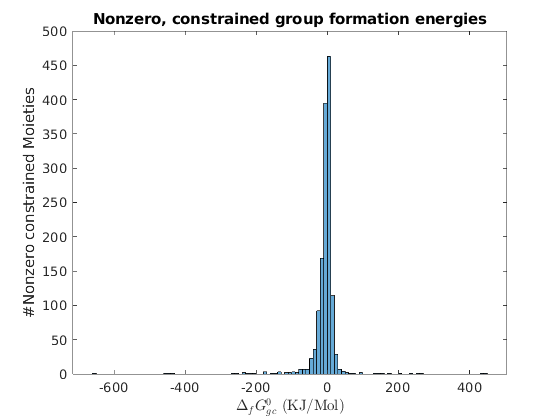

figure
histogram(solution.DfG0_gc(solution.DfG0_gc~=0 & ~solution.unconstrainedDfG0_gc))
title('Nonzero, constrained group formation energies')
xlabel('$\Delta_{f} G^{0}_{gc}$ (KJ/Mol)','Interpreter','latex')
ylabel('#Nonzero constrained Moieties')

nGroups =size(combinedModel.G,2);
fprintf('%u%s\n',nGroups,' estimated group formation energies')

5189 estimated group formation energies


 fprintf('%u%s\n',nnz(solution.unconstrainedDfG0_gc),' of which DfG0_gc(j) is unconstrained. i.e., group formation energies not constrained by group contribution')

3788 of which DfG0_gc(j) is unconstrained. i.e., group formation energies not constrained by group contribution


 fprintf('%g%s\n',nnz(solution.unconstrainedDfG0_gc)/nGroups,' fraction of unconstrained DfG0_gc')

0.730006 fraction of unconstrained DfG0_gc


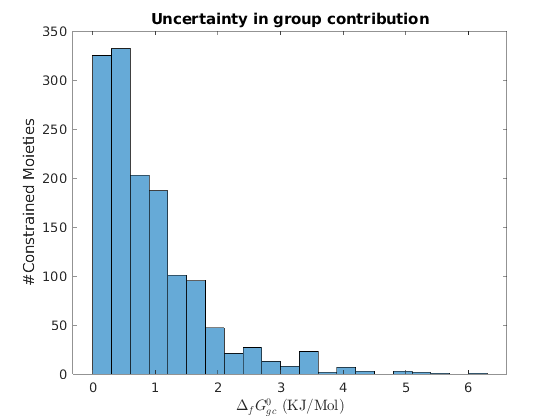

figure
histogram(solution.DfG0_gc_Uncertainty(~solution.unconstrainedDfG0_gc))
title('Uncertainty in group contribution')
ylabel('#Constrained Moieties')
xlabel('$\Delta_{f} G^{0}_{gc}$ (KJ/Mol)','Interpreter','latex')

fprintf('%g%s\n',nnz(solution.DfG0_gc_Uncertainty==0 & ~solution.unconstrainedDfG0_gc),' number of zero uncertainty in constrained DfG0_gc')

1 number of zero uncertainty in constrained DfG0_gc


fprintf('%g%s\n',nnz(solution.DfG0_gc_Uncertainty==0 & solution.unconstrainedDfG0_gc),' number of zero uncertainty in unconstrained DfG0_gc')

3788 number of zero uncertainty in unconstrained DfG0_gc


fprintf('%g%s\n',max(solution.DfG0_gc_Uncertainty),' maximum uncertainty for any group.')

6.26551 maximum uncertainty for any group.


Analyse the number of metabolites with different numbers of unconstrained Moieties

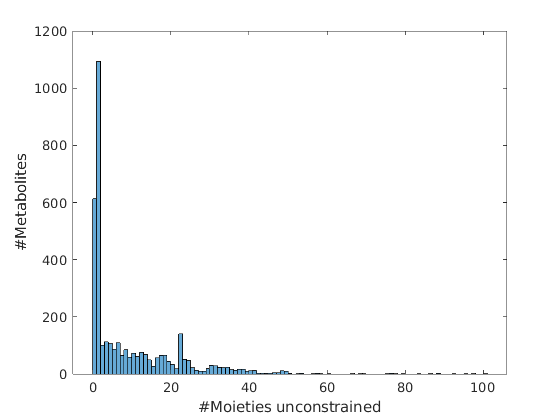

 nUnconstrainedGroupsPerMet = combinedModel.G*solution.unconstrainedDfG0_gc;
 figure
 histogram(nUnconstrainedGroupsPerMet,'BinWidth',1)
 xlabel('#Moieties unconstrained')
 ylabel('#Metabolites')

Conclusion: most metabolites only have one or two unconstrained Moieties.  

fprintf('%u%s\n',nnz(nUnconstrainedGroupsPerMet==0),' metabolites have no unconstrained moieties')

613 metabolites have no unconstrained moieties


fprintf('%u%s\n',nnz(nUnconstrainedGroupsPerMet),' metabolites have at least one unconstrained moiety')

3053 metabolites have at least one unconstrained moiety


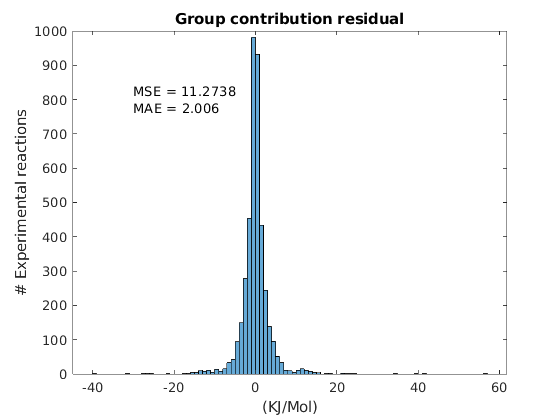

figure;
histogram(solution.e_gc)
title('Group contribution residual')
xlabel('(KJ/Mol)');
ylabel('# Experimental reactions')
text(-30,800,{['MSE = ' num2str(solution.MSE_gc)],['MAE = ' num2str(solution.MAE_gc)]});

[gcErrorSorted,gcSI]=sort(solution.e_gc);
 N=10;
 for i=1:N
     rxnFormula = printRxnFormula(combinedModel,'rxnAbbrList',combinedModel.rxns(gcSI(i)),'printFlag',0);
     fprintf('%g\t%s\t%s\n',solution.e_gc(rcSI(i)),combinedModel.rxns{gcSI(i)},rxnFormula{1});
 end

-31.6414	FORM_C06670	 -> C06670 
-26.9545	TECRDB_1919	C00002 + C01281  -> C00013 + C01299 
-21.9955	FORM_C00469	 -> C00469 
-25.3984	TECRDB_1929	C00002 + C01281  -> C00013 + C01299 
-15.9678	FORM_C00093	 -> C00093 
-15.2367	TECRDB_1920	C00002 + C01281  -> C00013 + C01299 
-15.6522	FORM_C00084	 -> C00084 
-13.3079	FORM_C80002	 -> C80002 
-15.3716	FORM_C01127	 -> C01127 
-12.4739	TECRDB_2655	C00003 + C00197  -> C00004 + C03232 


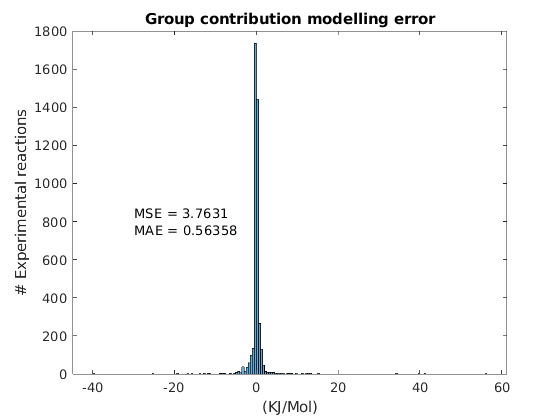

 figure;
 histogram(solution.e_m)
 title('Group contribution modelling error')
 xlabel('(KJ/Mol)');
 ylabel('# Experimental reactions')
 text(-30,800,{['MSE = ' num2str(solution.MSE_m)],['MAE = ' num2str(solution.MAE_m)]});

## Analyse component contribution

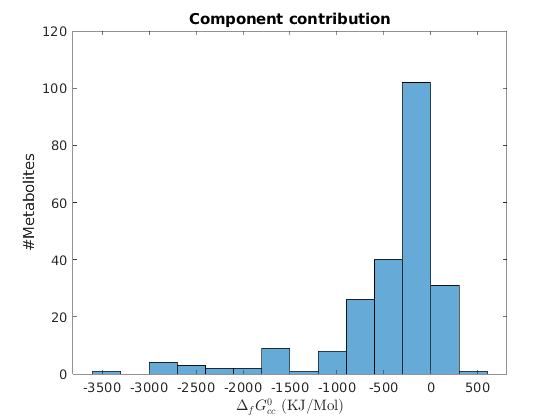

figure
histogram(solution.DfG0_cc(~solution.unconstrainedDfG0_cc))
title('Component contribution')
ylabel('#Metabolites')
xlabel('$\Delta_{f} G^{0}_{cc}$ (KJ/Mol)','Interpreter','latex')

fprintf('%u%s\n',length(solution.DfG0_cc),' estimated reactant formation energies.')

3666 estimated reactant formation energies.


fprintf('%u%s\n',nnz(solution.unconstrainedDfG0_cc),' of which DfG0_cc are partially unconstrained by component contribution')

3436 of which DfG0_cc are partially unconstrained by component contribution


fprintf('%g%s\n',nnz(solution.unconstrainedDfG0_cc)/length(solution.unconstrainedDfG0_cc),' = fraction of partially unconstrained DfG0_cc')

0.937261 = fraction of partially unconstrained DfG0_cc


Uncertainty in component contribution

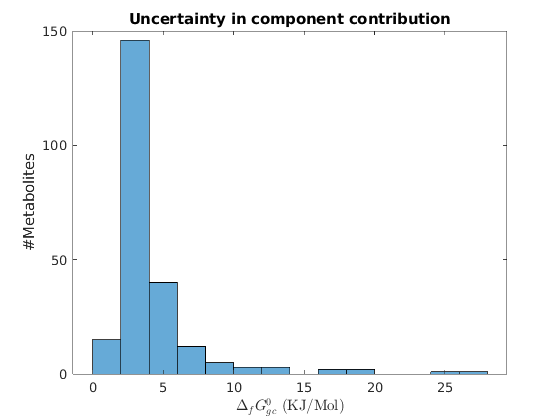

figure
histogram(solution.DfG0_cc_Uncertainty(~solution.unconstrainedDfG0_cc))
title('Uncertainty in component contribution')
ylabel('#Metabolites')
xlabel('$\Delta_{f} G^{0}_{gc}$ (KJ/Mol)','Interpreter','latex')

fprintf('%g%s\n',nnz(solution.DfG0_cc_Uncertainty==0 & ~solution.unconstrainedDfG0_cc),' number of zero uncertainty in constrained DfG0_cc')

1 number of zero uncertainty in constrained DfG0_cc


fprintf('%g%s\n',nnz(solution.DfG0_cc_Uncertainty==0 & solution.unconstrainedDfG0_cc),' number of zero uncertainty in unconstrained DfG0_cc')

0 number of zero uncertainty in unconstrained DfG0_cc


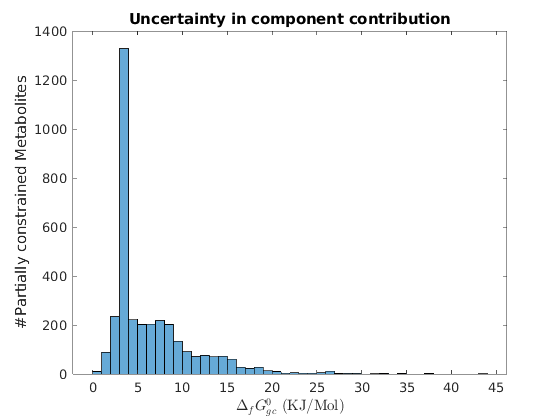

figure
histogram(solution.DfG0_cc_Uncertainty(solution.unconstrainedDfG0_cc))
title('Uncertainty in component contribution') 
ylabel('#Partially constrained Metabolites')
xlabel('$\Delta_{f} G^{0}_{gc}$ (KJ/Mol)','Interpreter','latex')

Breakdown of contributions to uncertainty in component contribution. Bar graph, with one bar for each reaction (row of the matrix). The height of each bar is the sum of the uncertainties in the reaction (row).

figure
Y = [solution.DfG0_cc_inf_Uncertainty,solution.DfG0_cc_gc_Uncertainty,solution.DfG0_rc_Uncertainty];

Sort by uncertainty in reactant contribution (for each metabolite)

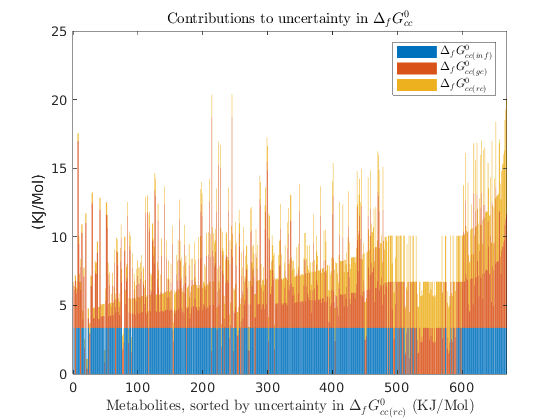

[~,xi]=sort(solution.DfG0_rc_Uncertainty);
bar(Y(xi(solution.DfG0_rc_Uncertainty(xi)~=0),:),'stacked')
title('Contributions to uncertainty in $\Delta_{f} G^{0}_{cc}$','Interpreter','latex')
xlabel('Metabolites, sorted by uncertainty in $\Delta_{f} G^{0}_{cc(rc)}$ (KJ/Mol)','Interpreter','latex')
ylabel('(KJ/Mol)')
legend({'$\Delta_{f} G^{0}_{cc(inf)}$','$\Delta_{f} G^{0}_{cc(gc)}$','$\Delta_{f} G^{0}_{cc(rc)}$'},'Interpreter','latex')

Sort by uncertainty in group contribution (for each metabolite)

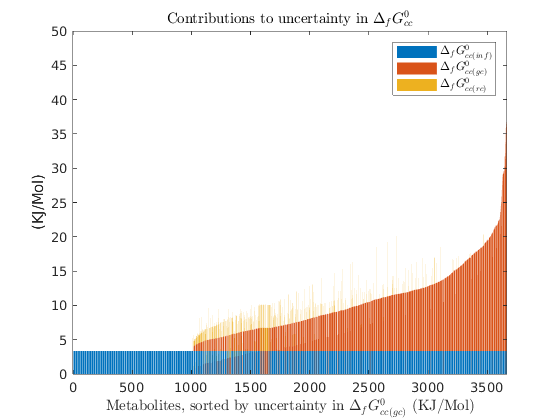

[~,xi]=sort(solution.DfG0_cc_gc_Uncertainty);
bar(Y(xi,:),'stacked')
title('Contributions to uncertainty in $\Delta_{f} G^{0}_{cc}$','Interpreter','latex')
xlabel('Metabolites, sorted by uncertainty in $\Delta_{f} G^{0}_{cc(gc)}$ (KJ/Mol)','Interpreter','latex')
ylabel('(KJ/Mol)')
legend({'$\Delta_{f} G^{0}_{cc(inf)}$','$\Delta_{f} G^{0}_{cc(gc)}$','$\Delta_{f} G^{0}_{cc(rc)}$'},'Interpreter','latex')

Component contribution model fitting residual

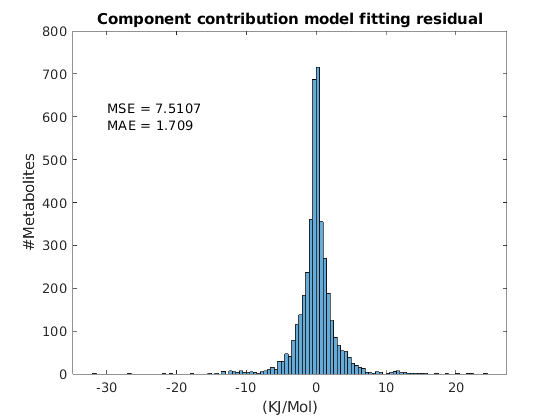

figure;
histogram(solution.e_cc)
text(-30,600,{['MSE = ' num2str(solution.MSE_cc)],['MAE = ' num2str(solution.MAE_cc)]});
title('Component contribution model fitting residual')
xlabel('(KJ/Mol)')
ylabel('#Metabolites')

 [ccErrorSorted,ccSI]=sort(solution.e_cc);
 N=10;
 for i=1:N
     rxnFormula = printRxnFormula(combinedModel,'rxnAbbrList',combinedModel.rxns(ccSI(i)),'printFlag',0);
     fprintf('%g\t%s\t%s\n',solution.e_cc(ccSI(i)),combinedModel.rxns{ccSI(i)},rxnFormula{1});
 end

-31.6414	TECRDB_1919	C00002 + C01281  -> C00013 + C01299 
-26.9545	TECRDB_1929	C00002 + C01281  -> C00013 + C01299 
-21.9955	TECRDB_1920	C00002 + C01281  -> C00013 + C01299 
-20.5893	FORM_C00093	 -> C00093 
-17.7694	FORM_C01127	 -> C01127 
-15.2367	TECRDB_539	C00002 + C00300  -> C00008 + C02305 
-15.1381	TECRDB_2655	C00003 + C00197  -> C00004 + C03232 
-14.375	TECRDB_3728	C00003 + C00469  -> C00004 + C00084 
-14.2817	TECRDB_374	C00006 + C00342  -> C00005 + C00343 
-13.4218	TECRDB_237	C00002 + C00062  -> C00008 + C05945 


## Comparison of weighting of reactant and group contribution for test metabolites

clear X
X(combinedModel.test2CombinedModelMap,:) = model.S;
XR = solution.PR_St*X;
XN = solution.PN_St*X;
XNR = (solution.PN_St - solution.PN_StGGt)*X;
XNN = solution.PN_StGGt*X;

Check that the decomposition into different components is complete

norm(X - (XR + XNR + XNN),'inf')

ans = 1.5682e-15

Stoichiometric degree

dX = diag(X*X');
fprintf('%u%s\n',nnz(dX),' metabolites with non-zero test stoichiometric degree')

3128 metabolites with non-zero test stoichiometric degree


fprintf('%u%s\n',nnz(dX==0),' metabolites with zero test stoichiometric degree')

538 metabolites with zero test stoichiometric degree


dXR = diag(XR*XR');
fprintf('%u%s\n',nnz(dX),' metabolites with non-zero test stoichiometric degree, in the range of S''')

3128 metabolites with non-zero test stoichiometric degree, in the range of S'


fprintf('%u%s\n',nnz(dX==0),' metabolites with zero test stoichiometric degree, in the range of S''')

538 metabolites with zero test stoichiometric degree, in the range of S'


dXN = diag(XN*XN');
fprintf('%u%s\n',nnz(dXN),' metabolites with non-zero test stoichiometric degree, in the nullspace of S''')

3511 metabolites with non-zero test stoichiometric degree, in the nullspace of S'


fprintf('%u%s\n',nnz(dXN==0),' metabolites with zero test stoichiometric degree, in the nullspace of S''')

155 metabolites with zero test stoichiometric degree, in the nullspace of S'


dXNR = diag(XNR*XNR');
fprintf('%u%s\n',nnz(dXNR),' metabolites with non-zero test stoichiometric degree, in the nullspace of S'' and G''x in the range of G''S')

3470 metabolites with non-zero test stoichiometric degree, in the nullspace of S' and G'x in the range of G'S


fprintf('%u%s\n',nnz(dXNR==0),' metabolites with zero test stoichiometric degree, in the nullspace of S'' and G''x in the range of G''S')

196 metabolites with zero test stoichiometric degree, in the nullspace of S' and G'x in the range of G'S


dXNN = diag(XNN*XNN');
fprintf('%u%s\n',nnz(dXNN),' metabolites with non-zero test stoichiometric degree, in the nullspace of S'' and in the nullspace of S''GG'' ')

3656 metabolites with non-zero test stoichiometric degree, in the nullspace of S' and in the nullspace of S'GG' 


fprintf('%u%s\n',nnz(dXNN==0),' metabolites with zero test stoichiometric degree, in the nullspace of S'' and in the nullspace of S''GG'' ')

10 metabolites with zero test stoichiometric degree, in the nullspace of S' and in the nullspace of S'GG' 


Sort by stoichiometric degree of reactant contribution (for each metabolite)

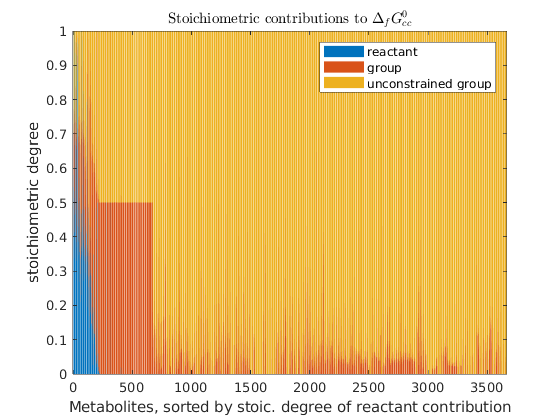

dXtotal = dXR + dXNR + dXNN;
Y = [dXR./dXtotal,dXNR./dXtotal,dXNN./dXtotal];
[dXRsorted,xi]=sort(dXR,'descend');
figure
bar(Y(xi,:),'stacked')
ylim([0 1])
title('Stoichiometric contributions to $\Delta_{f} G^{0}_{cc}$','Interpreter','latex')
xlabel('Metabolites, sorted by stoic. degree of reactant contribution')
ylabel('stoichiometric degree')
legend({'reactant','group','unconstrained group'})

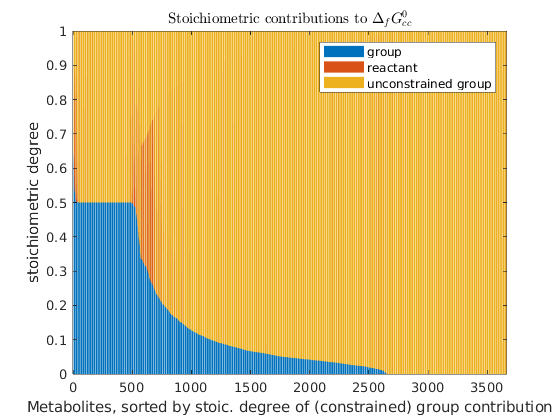

Y = [dXNR./dXtotal,dXR./dXtotal,dXNN./dXtotal];
[~,xi]=sort(dXNR./dXtotal,'descend');
figure
bar(Y(xi,:),'stacked')
ylim([0 1])
title('Stoichiometric contributions to $\Delta_{f} G^{0}_{cc}$','Interpreter','latex')
xlabel('Metabolites, sorted by stoic. degree of (constrained) group contribution')
ylabel('stoichiometric degree')
legend({'group','reactant','unconstrained group'})

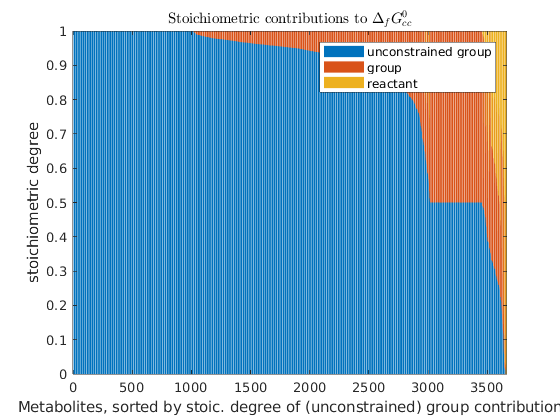

Y = [dXNN./dXtotal,dXNR./dXtotal,dXR./dXtotal];
[~,xi]=sort(dXNN./dXtotal,'descend');
figure
bar(Y(xi,:),'stacked')
ylim([0 1])
title('Stoichiometric contributions to $\Delta_{f} G^{0}_{cc}$','Interpreter','latex')
xlabel('Metabolites, sorted by stoic. degree of (unconstrained) group contribution')
ylabel('stoichiometric degree')
legend({'unconstrained group','group','reactant'})

## Analyse reacting moieties in the test model

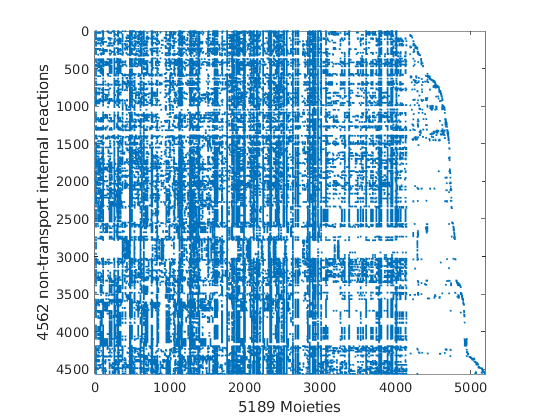

transportRxnBool = transportReactionBool(model);
model.G=combinedModel.G(combinedModel.test2CombinedModelMap,:);
StG=model.S'*model.G;
bool = model.SIntRxnBool & ~transportRxnBool;
figure
spy(StG(bool,:))
xlabel([int2str(size(StG(bool,:),2)) ' Moieties'])
ylabel([int2str(size(StG(bool,:),1)) ' non-transport internal reactions'])

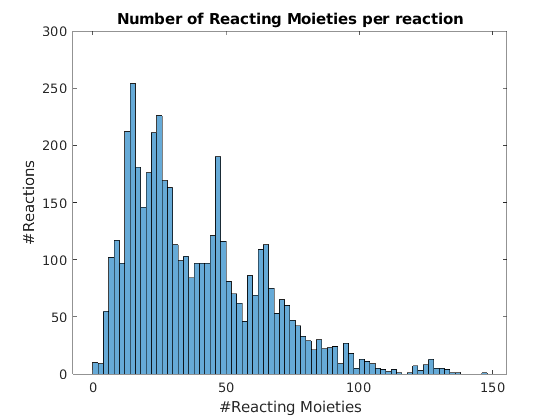

nReactingMoieties=full(sum(StG~=0,2));
histogram(nReactingMoieties(bool),'BinWidth',2)
title('Number of Reacting Moieties per reaction')
xlabel('#Reacting Moieties')
ylabel('#Reactions')

fprintf('%u%s\n',nnz(nReactingMoieties==0 & bool),' internal non-transport reactions without reacting moieties.')

10 internal non-transport reactions without reacting moieties.


printRxnFormula(model,model.rxns(bool & nReactingMoieties==0));

CYSGLTH	Lcystin[c] + 2 gthrd[c] 	<=>	2 cys_L[c] + gthox[c] 
NDPK8m	atp[m] + dadp[m] 	->	adp[m] + datp[m] 
NDPK8n	atp[n] + dadp[n] 	<=>	datp[n] + adp[n] 
RAI2	retinal[c] 	<=>	retinal_cis_9[c] 
RETI2	retinol[c] 	<=>	retinol_9_cis[c] 
TMDPPK	atp[c] + thmpp[c] 	->	adp[c] + thmtp[c] 
RE2651R	retinal[r] 	<=>	retinal_cis_9[r] 
RE3002X	CE5114[x] 	<=>	CE5116[x] 
NDPK8	atp[c] + dadp[c] 	<=>	adp[c] + datp[c] 
HMR_3447	CE5116[m] 	->	CE5114[m] 


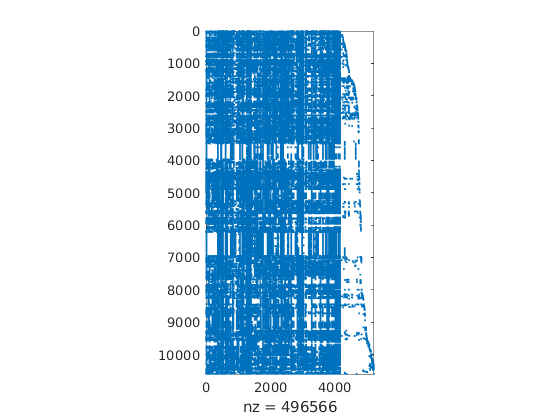

AtG=(model.S~=0)'*model.G;
spy(AtG)

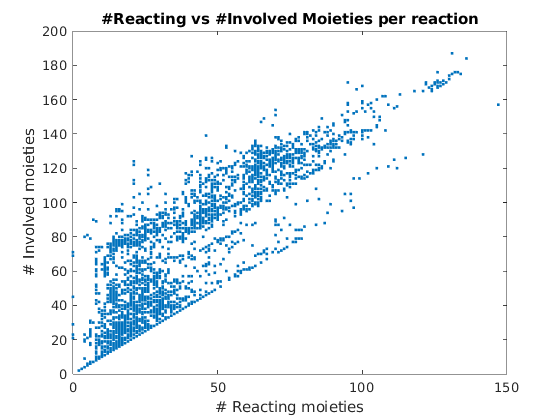

nInvolvedMoieties=full(sum(AtG~=0,2));
bool = model.SIntRxnBool & ~transportRxnBool;
plot(nReactingMoieties(bool),nInvolvedMoieties(bool),'.')
xlabel('# Reacting moieties')
ylabel('# Involved moieties')
title('#Reacting vs #Involved Moieties per reaction')

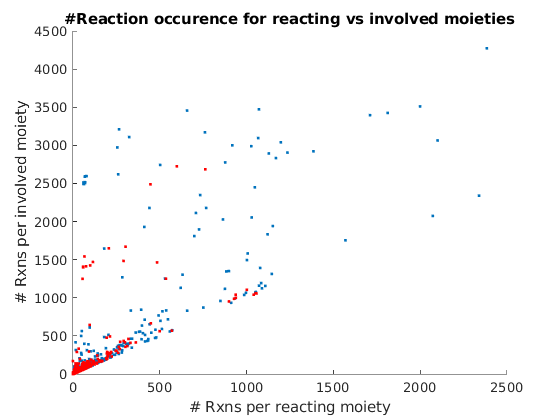

nRxnsMoietiesInvolved=full(sum(AtG(bool,:)~=0,1)');
nRxnsMoietiesReacting=full(sum(StG(bool,:)~=0,1)');
figure
hold on
plot(nRxnsMoietiesReacting,nRxnsMoietiesInvolved,'.')
plot(nRxnsMoietiesReacting(solution.unconstrainedDfG0_gc),nRxnsMoietiesInvolved(solution.unconstrainedDfG0_gc),'.r')
hold off
xlabel('# Rxns per reacting moiety')
ylabel('# Rxns per involved moiety')
title('#Reaction occurence for reacting vs involved moieties')

Moieties reacting in a lot of reactions but unconstrained by group contribution

T = table(combinedModel.groups(nRxnsMoietiesReacting>1000 & solution.unconstrainedDfG0_gc),nRxnsMoietiesReacting(nRxnsMoietiesReacting>1000 & solution.unconstrainedDfG0_gc),'VariableNames',{'Reacting_Moiety','#Reactions'});
disp(T)

        Reacting_Moiety         #Reactions
    ________________________    __________

    {'C/C(=N)[O-]'         }       1057   
    {'C=C(C)/C(=N)[O-]'    }       1041   
    {'CCC(=CN)/C(=N)[O-]'  }       1041   
    {'C[C@@H](n)O'         }       1001   
    {'c/C(=N)[O-]'         }       1054   
    {'cc(c)/C(=N)[O-]'     }       1052   
    {'ccc(c[n+])/C(=N)[O-]'}       1052   



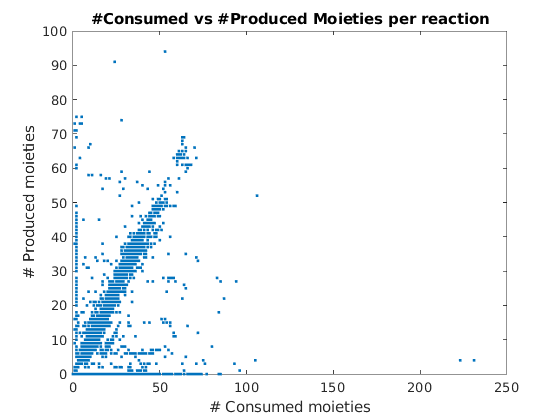

nConsumedMoieties=sum(StG<0,2);
nProducedMoieties=sum(StG>0,2);
plot(nConsumedMoieties,nProducedMoieties,'.')
xlabel('# Consumed moieties')
ylabel('# Produced moieties')
title('#Consumed vs #Produced Moieties per reaction')

## Reaction Component contribution taking into account reacting moieties only

nnz(solution.unconstrainedDfG0_cc)

ans = 3436


bool = model.SIntRxnBool & ~transportRxnBool;
fprintf('%u%s\n',nnz(bool),' internal non-transport reactions.')

4562 internal non-transport reactions.


fprintf('%u%s\n',nnz(model.unconstrainedDrG0_cc & bool),' of which have unconstrained DrG0.')

1419 of which have unconstrained DrG0.


ind=find(model.unconstrainedDrG0_cc & bool);

## Estimated standard reaction Gibbs energy

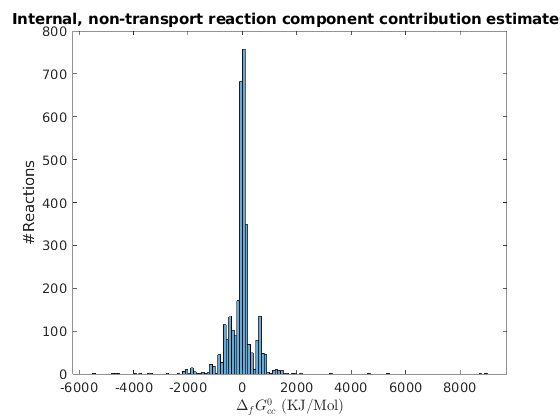

 figure;
 bool = model.SIntRxnBool & ~transportRxnBool & ~model.unconstrainedDrG0_cc;
 histogram(model.DrG0(bool))
 title('Internal, non-transport reaction component contribution estimates')
 ylabel('#Reactions')
 xlabel('$\Delta_{f} G^{0}_{cc}$ (KJ/Mol)','Interpreter','latex')

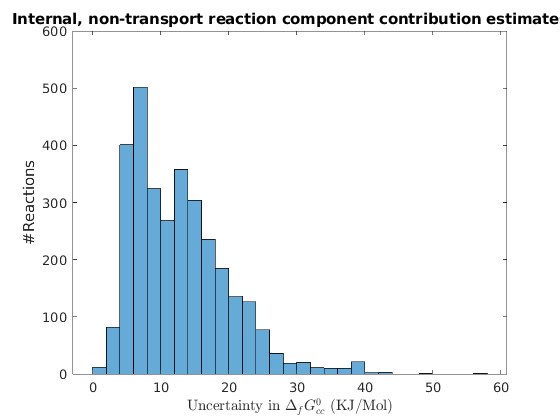

 figure;
 bool = model.SIntRxnBool & ~transportRxnBool & ~model.unconstrainedDrG0_cc;
 histogram(model.DrG0_Uncertainty(bool))
 title('Internal, non-transport reaction component contribution estimates')
 ylabel('#Reactions')
 xlabel('Uncertainty in $\Delta_{f} G^{0}_{cc}$ (KJ/Mol)','Interpreter','latex')

## Estimated standard metabolite Gibbs energy vs molecular mass

figure
[metMasses, knownMasses, unknownElements, Ematrix, elements] = getMolecularMass(model.metFormulas);

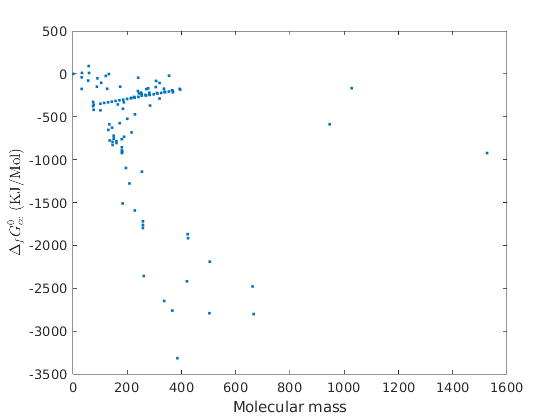

plot(metMasses(~model.unconstrainedDfG0_cc),model.DfG0(~model.unconstrainedDfG0_cc),'.')
xlabel('Molecular mass')
ylabel('$\Delta_{f} G^{0}_{cc}$ (KJ/Mol)','Interpreter','latex')

## Estimated standard reaction Gibbs energy vs bonds broken and formed

inputFolder = ['~' filesep 'work' filesep 'sbgCloud' filesep 'programExperimental' filesep 'projects' filesep 'xomics' filesep 'data' filesep 'Recon3D_301'];
BBFmodel = load([inputFolder filesep 'Recon3DModel_301_thermo_BBF.mat']);
%BBFmodel = load('~/work/sbgCloud/programExperimental/projects/xomics/data/Recon3D_301/Recon3DModel_301_thermo_BBF');
BBFmodel=BBFmodel.model;

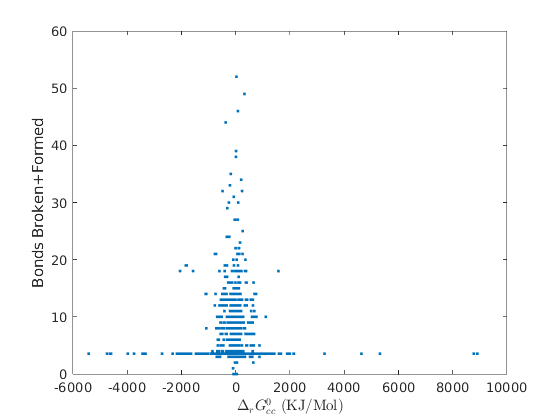

model.transportRxnBool = transportReactionBool(model);
bool = ~model.unconstrainedDrG0_cc & model.SIntRxnBool & ~model.transportRxnBool;
DfG0_cc = solution.DfG0_cc(combinedModel.test2CombinedModelMap);
DrG0_cc = model.S'*DfG0_cc;
figure
plot(DrG0_cc(bool),BBFmodel.bondsBF(bool),'.')
ylabel('Bonds Broken+Formed')
xlabel('$\Delta_{r} G^{0}_{cc}$ (KJ/Mol)','Interpreter','latex')

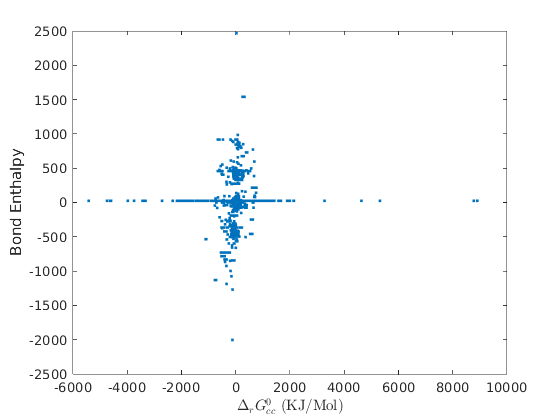


plot(DrG0_cc(bool),BBFmodel.bondsE(bool),'.') 
ylabel('Bond Enthalpy')
xlabel('$\Delta_{r} G^{0}_{cc}$ (KJ/Mol)','Interpreter','latex')

% unconstrainedDfG0_cc = model.S
% 
% %DfG0_cc = PR_St * DfG0_rc + PN_St * G * DfG0_gc;
% DfG0_cc = PR_St * DfG0_rc + PN_St * G * DfG0_gc;
% model.PR_St=solution.PR_St(combinedModel.test2CombinedModelMap,:);
% model.PN_St=solution.PN_St(combinedModel.test2CombinedModelMap,:);
% DrG0_rc = model.S'*model.PR_St*solution.DfG0_rc + model.S'*model.PN_St * solution.G * solution.DfG0_gc;
% 
% %identify the component contribution estimates that are unconstrained
% reactantContUnconstrainedDfG0_cc = (PR_St * unconstrainedDfG0_rc)~=0;
% groupContUnconstrainedDfG0_cc = (PN_St * G * unconstrainedDfG0_gc)~=0;
% unconstrainedDfG0_cc = (PR_St * unconstrainedDfG0_rc + PN_St * G * unconstrainedDfG0_gc)~=0;

% DrG0_cc = model.S'*model.PR_St*solution.DfG0_rc + model.S'*model.PN_St * solution.G * solution.DfG0_gc;